% dtft (infinite sampling)
w = linspace(0,2*pi,200);
dtft = exp(-2*1j*w).*(sin(5*w/2)./sin(w/2));
plot(w, abs(dtft))
hold on
% dft (spaced out sampling)
s = [1 1 1 1 1 0 0 0 0 0];
dft = fft(s);
whos

  Name      Size             Bytes  Class     Attributes

  dft       1x10               160  double    complex   
  dtft      1x200             3200  double    complex   
  s         1x10                80  double              
  w         1x200             1600  double              
  ws        1x100              800  double              



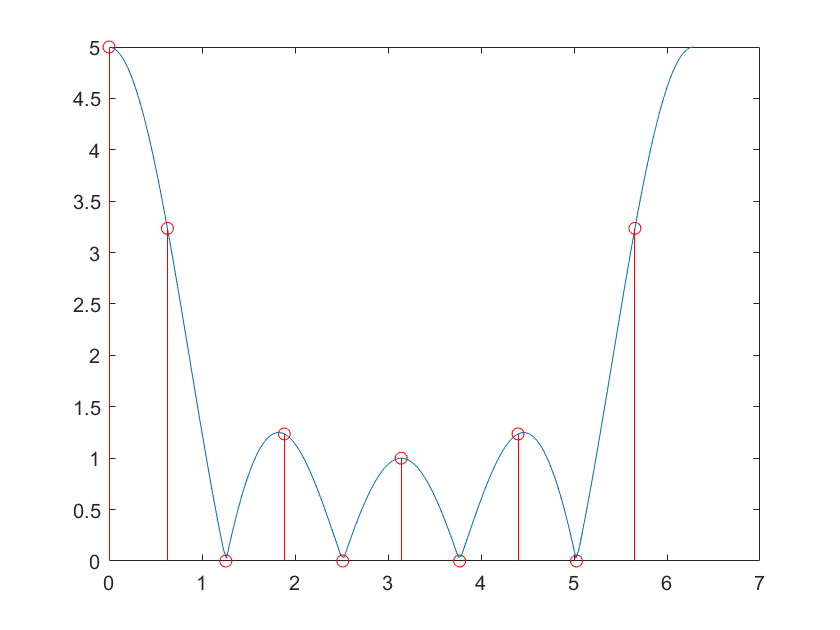

ws = 2*pi/10*[0:9];
stem(ws, abs(dft),'r')
hold off


% dft (more sampling)
s = [ones(1,5), zeros(1,95)];
dft=fft(s);
whos

  Name      Size             Bytes  Class     Attributes

  dft       1x100             1600  double    complex   
  dtft      1x200             3200  double    complex   
  s         1x100              800  double              
  w         1x200             1600  double              
  ws        1x10                80  double              



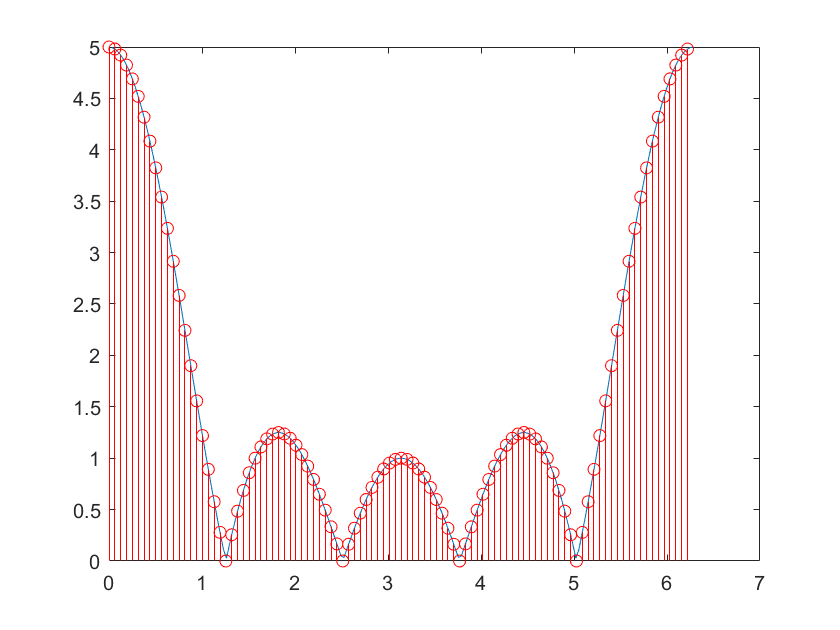

plot(w,abs(dtft))
hold on
ws = 2*pi/100*[0:99];
stem(ws, abs(dft),'r')
hold off


% without using ws, we can use the built-in 
% fft to perform the samething!
% i want dft to be length 100
dft = fft(s,50);
whos

  Name      Size             Bytes  Class     Attributes

  dft       1x50               800  double    complex   
  dtft      1x200             3200  double    complex   
  s         1x100              800  double              
  w         1x200             1600  double              
  ws        1x100              800  double              



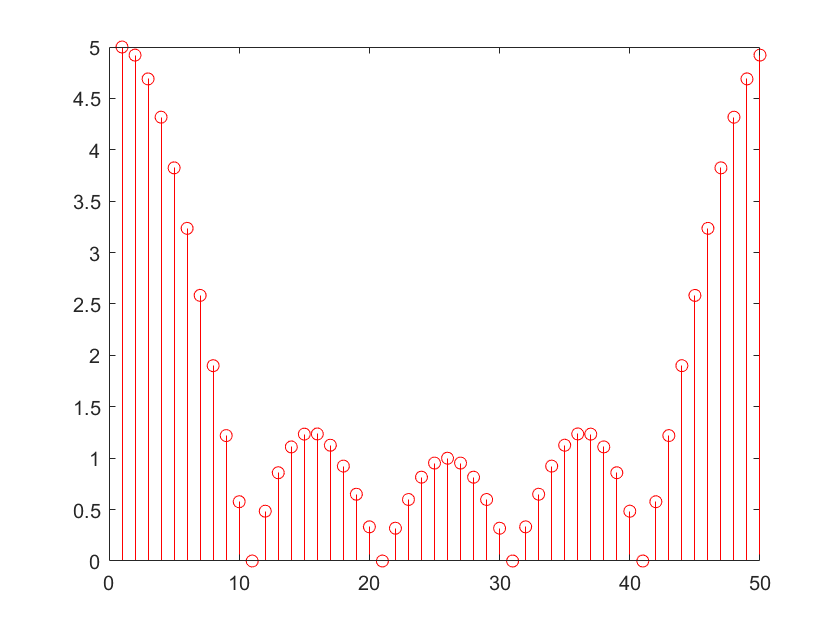

stem(abs(dft),'r')